## Лабораторная работа №8

### Задание: по временному уравнению Шрёдингера получить волну в разные моменты времени (0, 34, 68fs).

clc; clear;

xLimit = 40e-9;
tLimit = 100e-15;

xCount = 500;
tCount = 10000;

hbar = 1.055e-34;
m0 = 9.109e-31;
meff = 1;
m = m0 * meff;

la = 5e-9;
s = 3e-9;

start = xLimit / 3;

const = hbar / (2 * m) * (tLimit / tCount) / (xLimit / xCount) ^2;

Всего лишь начальные задания переменных, где xLimit, tLimit - пределы нахождения (построения), xCount, tCount - количество шагов, start - центр волны в t = 0; const - проверяемый множитель.

P.S. потенциальная энергия в расчёт не бралась.

if const > 0.15
    throw(MException('MATLAB:divideByZero', 'Too big steps'));
end

Если что-то пойдёт не так, и константа превысит допустимые пределы - дальше не пройти. Со значениями стартовыми можно играться, но большая часть игр закончится здесь.

stepByStep = zeros(2 * tCount, xCount);

startIm = @(x) exp(-0.5 * ((x - start) / s) .^ 2) .* sin ( (2 * pi * (x - start)) / la );
startRe = @(x) exp(-0.5 * ((x - start) / s) .^ 2) .* cos ( (2 * pi * (x - start)) / la );

stepByStep - великая матрица с говорящим названием. Нечетные строчки - мнимые части в периоды времени. Четные - действительные.

startIm, startRe - функции просчёта начальных значений (введение частицы в t = 0).

xLin = linspace(0, xLimit, xCount);

stepByStep(1, :) = startIm(xLin);
stepByStep(2, :) = startRe(xLin);

stepByStep(:, 1) = 0; stepByStep(:, xCount) = 0;

Размечаем стартовые значения, вводим граничные условия.

for t = 3 : tCount * 2
    for x = 2 : xCount - 1
        temporary = const * (stepByStep(t - 1, x - 1) - 2 * ...
            stepByStep(t - 1, x) + stepByStep(t - 1, x + 1));
        if mod(t, 2) == 0 
            temporary = temporary * -1;
        end
        stepByStep(t, x) = stepByStep(t - 2, x) + temporary;
    end
end

Все фокусы здесь. За шаг внешнего цикла присходит просчёт строчки (мнимой или действительной части на всей заданной x).

for t = 1 : 2 : tCount*2 - 1
    stepByStep([t, t+1], :) = stepByStep([t, t+1], :) /...
        sum(stepByStep(t, :) .^ 2 + stepByStep(t + 1, :) .^ 2);
end

Нормировка здесь, потому что я забыл сделать раньше. Далее просто строятся графики. Разница с опорным скриптом заключается в том, что там значения пси считались на необходимый интервал. Я же, как владелец большого жесткого диска, предпочитаю просчитать много, но всё за раз. Далее просто строить.

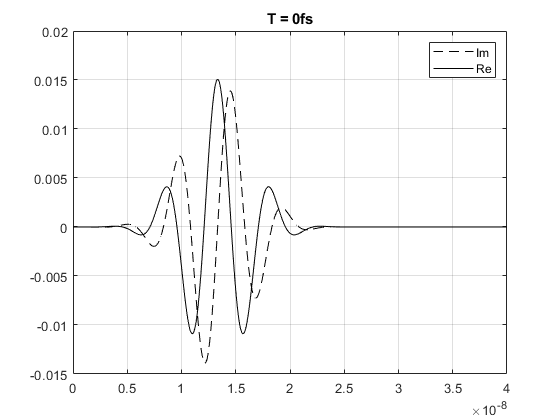

figure;
timeToPlot = 0;
plot(xLin, stepByStep(timeToPlot * 2+1, :), 'k--'); hold on;
plot(xLin, stepByStep(timeToPlot * 2+2, :), 'k'); grid on;
title('T = 0fs');
legend('Im', 'Re');

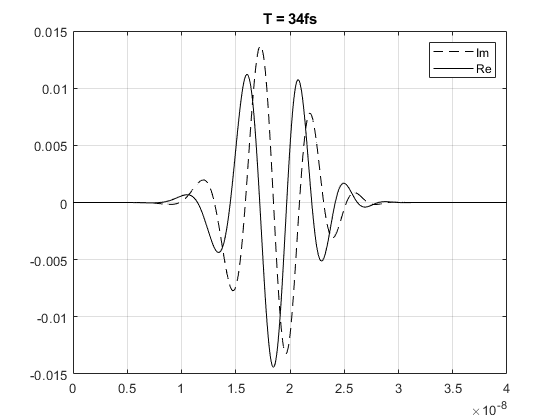


figure;
timeToPlot = 3400;
plot(xLin, stepByStep(timeToPlot * 2+1, :), 'k--'); hold on;
plot(xLin, stepByStep(timeToPlot * 2+2, :), 'k'); grid on;
title('T = 34fs');
legend('Im', 'Re');

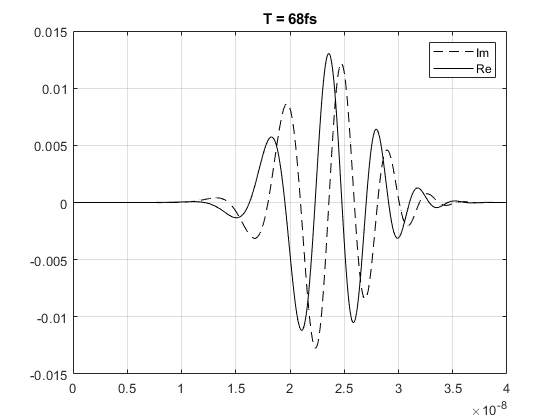


figure;
timeToPlot = 6800;
plot(xLin, stepByStep(timeToPlot * 2+1, :), 'k--'); hold on;
plot(xLin, stepByStep(timeToPlot * 2+2, :), 'k'); grid on;
title('T = 68fs');
legend('Im', 'Re');

#### Вывод: численным методом конечных разностей построили зависимость волновой функции от координаты в разные промежутки времени, использовав для начального условия стандартные волновые функции. Проследили эволюцию координаты и значений волны в разные моменты времени.